Impedance control characterization based on $x_e(t)$, $\dot{x}_e(t)$ and $f(t)$, for a 2º Order model with sinusoidal input.

close all
clear 
clc
% A = position error (deviation) input amplitude
% w_u = position error input frequency (angular)
syms s t A w_u K D M
% Recording: K, D, M -> w_n = sqrt(K/M), zeta = D/(2*M*w_n)
% Matlab assumptions simplifies the computation and avoid complex numbers
assume([t A w_u K D M], {'real','positive'})
Es = A * w_u/(s^2 + w_u^2);
Fs = (M*s^2 + D*s + K)*Es

$$Fs = \frac{A\,w_{u}\,\left(M\,s^{2}+\text{D}\,s+K\right)}{s^{2}+{w_{u}}^{2}}$$

Et = ilaplace(Es);
dEt = ilaplace(s*Es);
Ft = ilaplace(Fs);
f_expr = latex(simplify(Ft));
Ft

$$Ft = A\,K\,\sin\left(t\,w_{u}\right)+A\,\text{D}\,w_{u}\,\cos\left(t\,w_{u}\right)-A\,M\,{w_{u}}^{2}\,\sin\left(t\,w_{u}\right)$$

## Parametric curve (ellipse) {x_e, dx_e, f_ref} 

% to compute the gradient:
dFt = ilaplace(s*Fs);
Ft = simplify(Ft);
dFt = simplify(dFt);

Grad = [dEt, diff(dEt, t), dFt];                      % Gradient Vector
Tang = [diff(dEt, t), diff(dEt, t, 2), diff(dFt, t)]; % Tangent  Vector
N = cross(Grad, Tang);                                % Binormal Vector
N = simplify(N)

$$N = \left(\begin{array}{ccc} A^{2}\,{w_{u}}^{4}\,\left(K-M\,{w_{u}}^{2}\right) & A^{2}\,\text{D}\,{w_{u}}^{4} & -A^{2}\,{w_{u}}^{4} \end{array}\right)$$

Then, the normal vector can be simply defined as:

n_vec = [(K - M*w_u^2) D -1]

$$n\_vec = \left(\begin{array}{ccc} K-M\,{w_{u}}^{2} & \text{D} & -1 \end{array}\right)$$

n_expr = latex(N);
% Considering Tx, and Ty sequential rotations:
assume([t A w_u K D M], {'real','positive'})
phi = asin(-n_vec(1)/norm(n_vec)) % minus due to right hand rule

$$phi = -\mathrm{asin}\left(\frac{K-M\,{w_{u}}^{2}}{\sqrt{{\text{D}}^{2}+{\left|K-M\,{w_{u}}^{2}\right|}^{2}+1}}\right)$$

tht = atan(-n_vec(2)/n_vec(3))

$$tht = \mathrm{atan}\left(\text{D}\right)$$

%syms phi tht real
Tx  = [1 0 0; 0 cos(tht) -sin(tht); 0 sin(tht) cos(tht)];
Ty  = [cos(phi) 0 sin(phi); 0 1 0; -sin(phi) 0 cos(phi)];

% express the ellipse projection without the 'Tz':
Projection = (Tx*Ty)' * [Et dEt Ft]';
% explicit the cos(t*w_u), and sin(t*w_u) coefficients:
Projection = simplify( collect(Projection, [cos(t*w_u) sin(t*w_u)]) );

% extract the Projection terms on the x and y axes only (1,2) as functions of cosine and
% sine
P(1,1) = subs(Projection(1,1), [cos(w_u*t) sin(w_u*t)], [1 0]); % assuming sin = 1 and cos = 0 we get the sin coeff.
P(1,2) = subs(Projection(1,1), [cos(w_u*t) sin(w_u*t)], [0 1]); % assuming sin = 0 and cos = 1 we get the cos coeff.
P(2,1) = subs(Projection(2,1), [cos(w_u*t) sin(w_u*t)], [1 0]);
P(2,2) = subs(Projection(2,1), [cos(w_u*t) sin(w_u*t)], [0 1]);
P = simplify(P/A); % A is just scaling the matrix and we can remove it to assume the cos/ sin functions with amplitude A
%Tz = [P [0 0]'; 0 0 1];

% Derive the root ellipse semiaxes:
Q = abs(det(P));
R = P(1,1)^2 + P(2,1)^2 + P(1,2)^2 + P(2,2)^2;
Q = simplify(Q);
R = simplify(R);
a_x = simplify( 1/2*(sqrt(R + 2*Q) + sqrt(R - 2*Q)) );
b_x = simplify( 1/2*(sqrt(R + 2*Q) - sqrt(R - 2*Q)) );

## Plotting

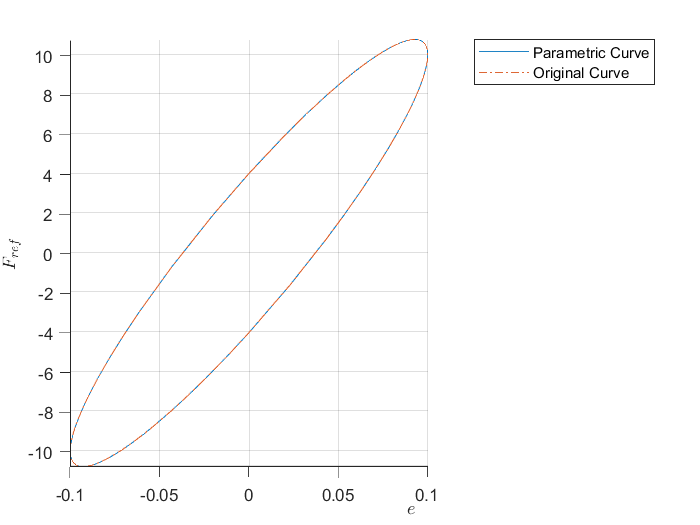

A0  = 0.1;
val_freq = 0.31831;      % => 2 rad/s
val_wu = 2*pi*val_freq;
Kd = 100; Dd = 2*sqrt(Kd); Md = 0;

Txy  = double( subs(Tx*Ty, [w_u K D M], [val_wu Kd Dd Md]));
Psbus = double( subs(P, [w_u K D M],  [val_wu Kd Dd Md]));
Tz = [Psbus [0 0]'; 0 0 1];

X = Txy*Tz*[A0*cos(val_wu*t), A0*sin(val_wu*t), 0]';
fplot3(X(1), X(2), X(3), [0 1/val_freq])
hold on
E  = subs(Et, [A w_u], [A0, val_wu]);
dE = subs(dEt, [A w_u], [A0, val_wu]);
F = subs(Ft, [A w_u K D M],  [A0 val_wu Kd Dd Md]);
fplot3(E, dE, F, [0 1/val_freq],'-.')
xlabel('$e$',"Interpreter","latex")
ylabel('$\dot{e}$',"Interpreter","latex")
zlabel('$F_{ref}$',"Interpreter","latex")
legend('Parametric Curve','Original Curve')
view([0.1 0.2])
hold off

% --- %

Inspecting the curve according to the parameters:

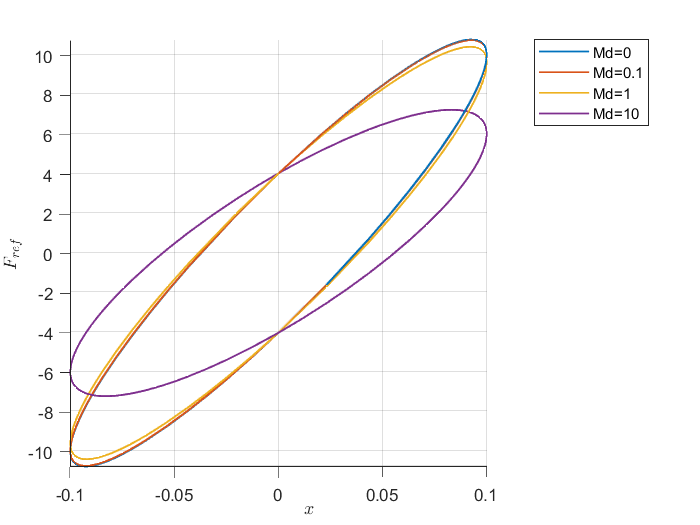

% Varying M
A0  = 0.1;
val_freq = 0.31831;      % => 2 rad/s
val_wu = 2*pi*val_freq;
Kd = 100; Dd = 2*sqrt(Kd);
md_array = [0 0.1 1 10];
figure
for Md = md_array
    Txy  = double( subs(Tx*Ty, [w_u K D M], [val_wu Kd Dd Md]));
    Psbus = double( subs(P, [w_u K D M],  [val_wu Kd Dd Md]));
    Tz = [Psbus [0 0]'; 0 0 1];

    X = Txy*Tz*[A0*cos(val_wu*t), A0*sin(val_wu*t), 0]';
    fplot3(X(1), X(2), X(3), [0 1/val_freq], 'LineWidth', 1.0, ...
           'DisplayName', strcat('Md= ', num2str(Md)))
    hold on
end

xlabel('$x$',"Interpreter","latex")
ylabel('$\dot{x}$',"Interpreter","latex")
zlabel('$F_{ref}$',"Interpreter","latex")
legend('show')
view([0.1 0.2])
hold off